Gradient descent

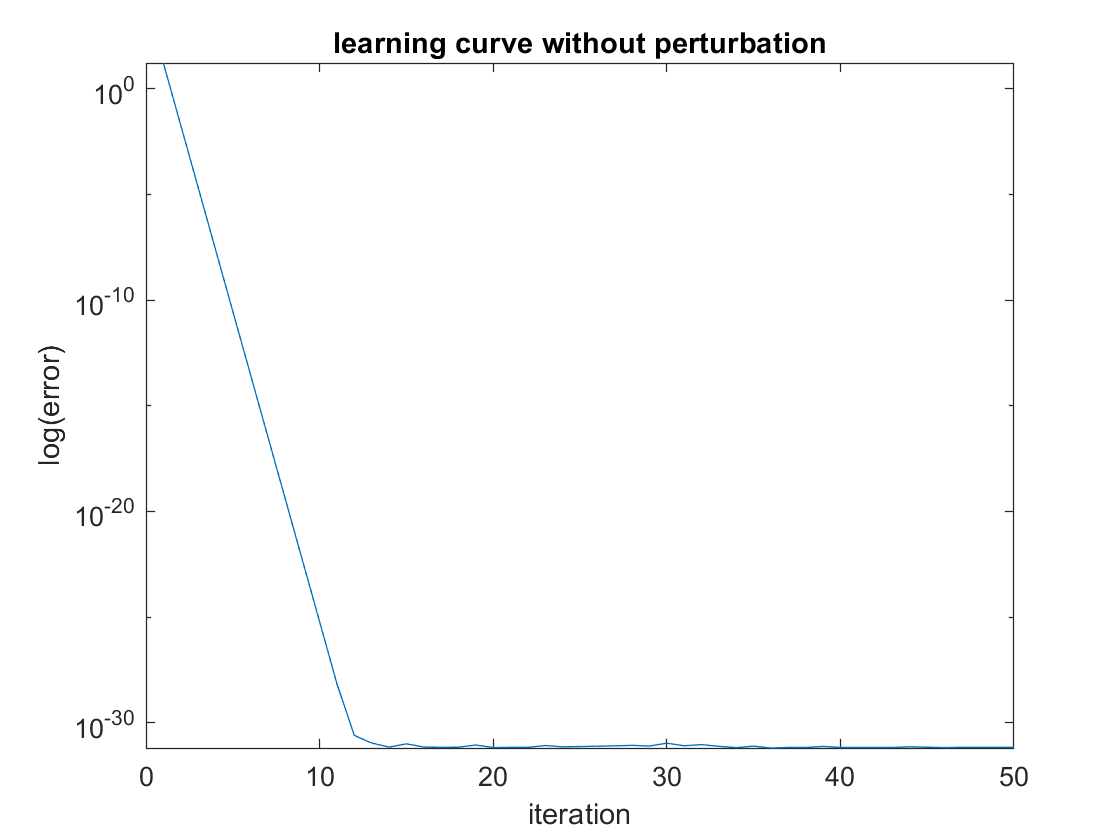

n = 10;
m = 20;
%sigma = 0.01;
iter = 50;
itag = 1/(2+n);
rng('default');
rng(2);
w = rand(m,n);
rng('default');
rng(1);
wtarget = rand(m,n);
W = w-wtarget;
rng('default');
rng(17);
x = normrnd(0,1,[n,1]);
etraj = zeros(1,iter);
for i = 1:iter
    e = 0.5*norm(W*x)^2;
    etraj(i) = e;
deltawg = -itag*W*(x*x');
W = W+deltawg;
end 
semilogy(etraj);
xlabel('iteration');
ylabel('log(error)');
title('learning curve without perturbation');

fite = log10(etraj);
[k, intercept] = polyfit(2:1:10,fite(2:10),1);

Weight perturbation

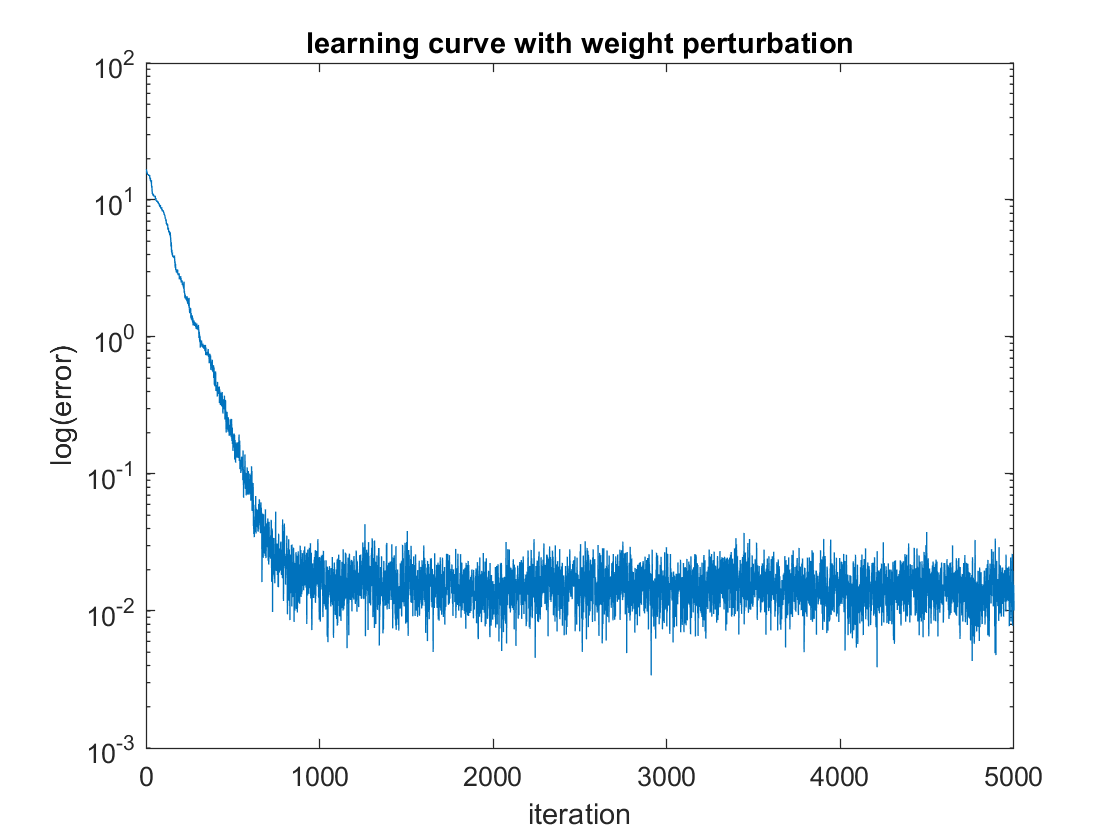

clear all;
n = 10;
m = 20;
sigma = 0.01;
iter = 5000;
itawp = 1/((m*n+2)*(n+2));
rng('default');
rng(2);
w = rand(m,n);
rng('default');
rng(1);
wtarget = rand(m,n);
W = w-wtarget;
rng('default');
rng(17);
x = normrnd(0,1,[n,1]);
etraj = zeros(1,iter);
%alpha = 0.1;
%eb = 0;
for i = 1:iter
ewp = normrnd(0,sigma,[m,n]);
eper = 0.5*norm(((W+ewp)*x))^2;
e = 0.5*norm(W*x)^2;
etraj(i) = eper;
deltawwp = -(itawp/(sigma^2))*(eper-e)*ewp;
%eb = (1-alpha)*eb+alpha*eper;
W = W+deltawwp;
end
semilogy(etraj);
xlabel('iteration');
ylabel('log(error)');
title('learning curve with weight perturbation');

fite = log10(etraj);
[k, intercept] = polyfit(1:1:400,fite(1:400),1);

   Node perturbation

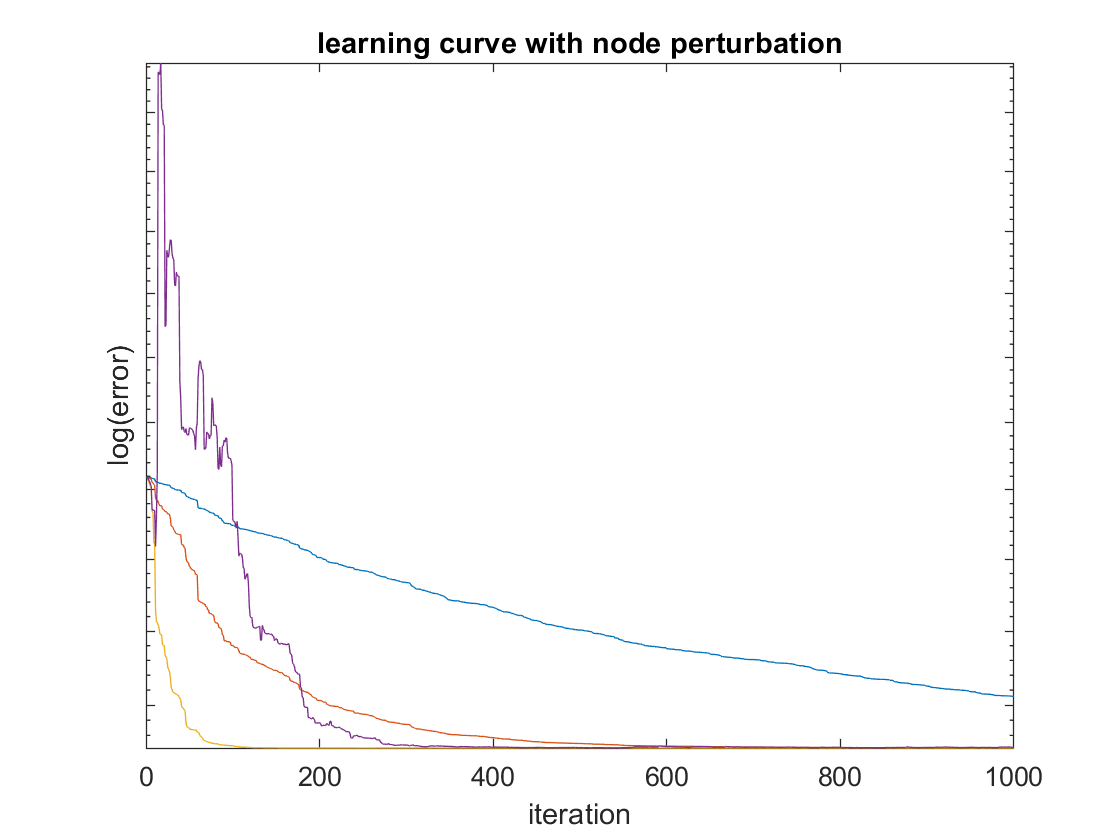

figure
n = 10;
m = 20;
sigma = 0.01;
iter = 1000;
lambda1 = [0.02 0.1 1 2 5];
%itanp = (1/((m+h+2)*(n+2)))*lambda;
for p = 1:length(lambda1)
itanp = 1/((m+2)*(n+2))*lambda1(p);
rng('default');
rng(2);
w = rand(m,n);
rng('default');
rng(1);
wtarget = rand(m,n);
W = w-wtarget;
%rng('default');
%rng(17);
x = normrnd(0,1,[n,1]);
etraj = zeros(1,iter);
eb = 0;
for i = 1:iter
enp = normrnd(0,sigma,[m,1]);
eper2 = 0.5*norm((W*x+enp),'fro')^2;
e = 0.5*norm(W*x,'fro')^2;
g_e = norm(W,'fro')^2;
etraj(i) = g_e;
deltawnp = -(itanp/sigma^2)*(eper2-e)*enp*x';
%eb = (1-alpha)*eb+alpha*eper2;
W = W+deltawnp;
end
if etraj(end) <= etraj(1)
semilogy(etraj);
xlabel('iteration');
ylabel('log(error)');
title('learning curve with node perturbation');
set(gca,'YTickLabel',[]);
hold on;
end
end

fite = log10(etraj);
[k, intercept] = polyfit(1:1:100,fite(1:100),1);

Node perturbation with running average

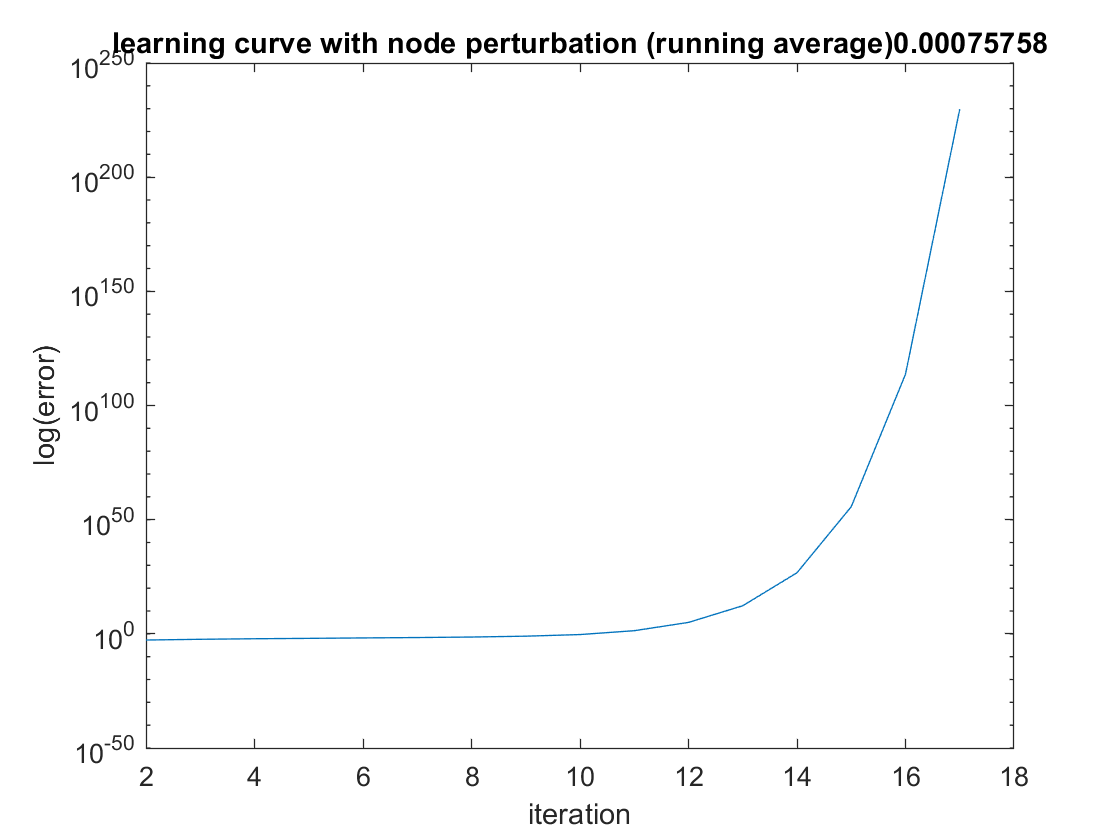

alpha = 0.05; % running average 20 time steps into the past
n = 10;
m = 20;
sigma = 0.01;
iter = 15000;
lambda = 0.2;
%lambda = [0.001 0.01 0.05 0.1 0.2];
%k = zeros(1,length(lambda));
figure
%set(gcf, 'Position',  [100, 100, 500, 800])
for j = 1:length(lambda)
itanp = (1/((m+2)*(n+2)))*lambda;
% rng('default');
% rng(2);
w = 0.05*rand(m,n);
% rng('default');
% rng(1);
wtarget = 0.05*rand(m,n);
W = w-wtarget;
rng('default');
rng(17);
x = normrnd(0,1,[n,1]);
etraj = zeros(1,iter);
%eb = 0.5*norm(W*x,'fro')^2;
eb = 0;
for i = 1:iter
enp = normrnd(0,sigma,[m,1]);
eper2 = 0.5*norm((W*x+enp),'fro')^2;
%e = 0.5*norm(W*x,'fro')^2;
etraj(i) = eb;
deltawnp = -(itanp/sigma^2)*(eper2-eb)*enp*x';
eb = (1-alpha)*eb+alpha*eper2;
W = W+deltawnp;
end
%subplot(5,1,j)
semilogy(etraj);
xlabel('iteration');
ylabel('log(error)');
title('learning curve with node perturbation (running average)'+string(itanp));
fite = log10(etraj);
[k, intercept] = polyfit(120:1:600,fite(120:600),1);
%k(1,j) = k(1,1);
end